# Parameter Estimation for CHIMERA-SIR models

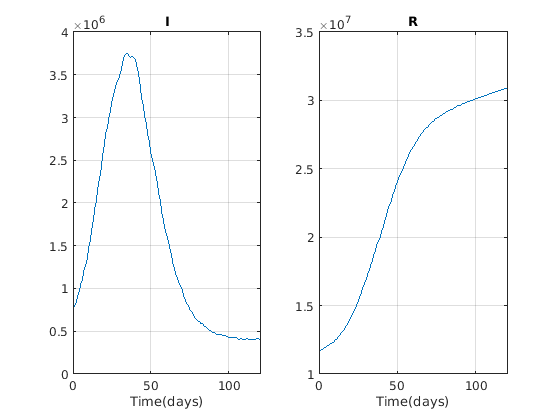

load("India.mat")

Cases = Cases - Recovered - Death;
ydata = [Cases(:, 440:end); Recovered(:, 440:end)];

VarNames={'S', 'I', 'R'};
OutNames={'S', 'I', 'R', 'R_{acc}', 'N'};
ParNames={'\gamma','\mu','z'};

FullNames = [VarNames,ParNames];

Range1 = [
    1e6 1.4e9; 
    ydata(1,1) ydata(1,1);
    ydata(2,1) ydata(2,1)
    ];

Range2=[
    0 4;          % gamma   
    0 0.1;        % mu
    0 10;         % z
    ];

RangeT = [Range1; Range2];

D = length(ydata(1,:));
Domain = [0 D-1];
xdata = 0:D-1;

for i = 1:2
    subplot(1,2,i)
    plot(ydata(i,:))
    grid on
    title(VarNames(i + 1))
    xlabel("Time(days)")
end

## Parameter estimation model simple and complex

ModelNames = ["simple", "complex"];

T_save = cell(2,1);     
N = 5000;
extra = struct();
Parameters = [];
Res = [];
 
for i = 1:2
    
    extra.Prob = i;
    %%Prob = 1 -> psi(simple)
    %%Pbro = 2 -> phi(complex)
    
    [T,~] = gsua_dataprep("CHIMERA_SIR", RangeT, 'domain', Domain, 'names',...
        FullNames, 'out_names', OutNames,'opt', extra);
    T.Properties.CustomProperties.output = [2,4];
    
    T_save{i} = T;
    
    Solver = 'lsqc';
        
    Opt = optimoptions('lsqcurvefit', 'UseParallel', false,'MaxFunctionEvaluations', 30000, ...
        'MaxIterations', 3000, 'Display','off');
    
    parfor j = 1:N
        [T_aux, Res_aux] = gsua_pe(T, xdata, ydata,...
            'solver', Solver,'N', 1,'opt', Opt,'save', false);
        Parameters(:,j) = T_aux.Estlsqc;
        Res(j) = Res_aux;
    end
    
    [Res, idx] = sort(Res);
    Parameters = Parameters(:,idx);
    
     

    save("Results/Estimations_India_lsqc_" + ModelNames(i), "Res",  "Parameters")
    
    figure
    gsua_eval(Parameters(:,1), T, xdata, ydata);
    suptitle(ModelNames(i) + " residual: " + Res(1))
end

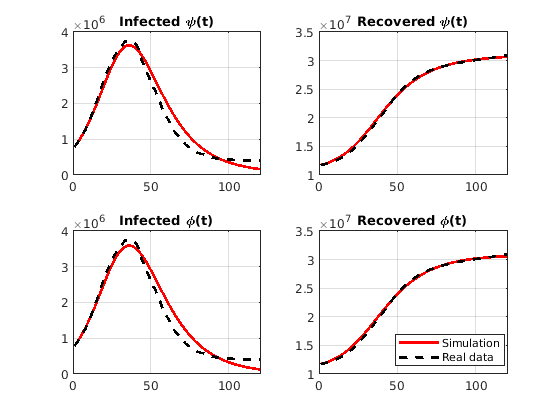

Files = ["Results/Estimations_India_lsqc_simple.mat","Results/Estimations_India_lsqc_complex.mat"];
Titles = ["Infected \psi(t)", "Recovered \psi(t)", "Infected \phi(t)", "Recovered \phi(t)"];

counter = 1;
figure

for k = 1:2 
    load(Files(k))
    N = size(Res, 2);
    ysim = zeros(N, 2, D);
    for i = 1:N
        ysim(i,:,:) = gsua_deval(Parameters(:,i)', T_save{k}, xdata);
        Res(i) = norm(squeeze(ysim(i,:,:)) - ydata);
    end
    [~, Idx] = sort(Res);
    IdxSims(k) = Idx(1);
    for j = 1:2        
        subplot(2,2,counter)
        plot(squeeze(ysim(IdxSims(k), j, :))', 'r','LineWidth',2); 
        hold on
        plot(ydata(j,:)','--k','LineWidth',2)
        grid on
        title(Titles(counter))
        counter = counter +1;
    end
end

legend({"Simulation", "Real data"}, 'location','best')

load(Files(1))
disp("S(0): " + Parameters(1,IdxSims(1)) + ", gamma: " + Parameters(2,IdxSims(1)) +...
    ", mu: " + Parameters(3,IdxSims(1)) + ", z: "+ Parameters(4,IdxSims(1)))

S(0): 20816980.7134, gamma: 2.3403, mu: 0.0020452, z: 0.27491


load(Files(2))
disp("S(0): " + Parameters(1,IdxSims(2)) + ", gamma: " + Parameters(2,IdxSims(2)) +...
    ", mu: " + Parameters(3,IdxSims(2)) + ", z: "+ Parameters(4,IdxSims(2)))

S(0): 22661117.0052, gamma: 2.3421, mu: 0.00087712, z: 0.27094


## Equilibriums

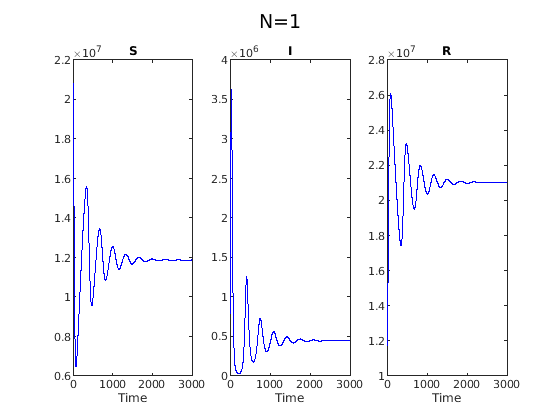

S = 11873374.0216 I = 447366.8945 R = 21015822.5515 N = 33336563.4676


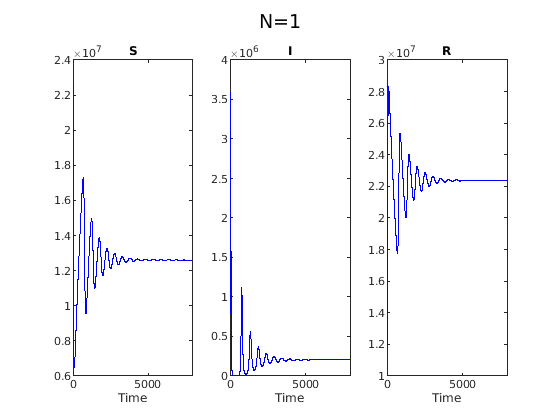

S = 12606897.219 I = 204316.4819 R = 22370405.3042 N = 35181619.0052


D2 = [3000, 7900];
for i = 1:2
    load(Files(i))    
    T_save{i}.Properties.CustomProperties.Domain(2) = D2(i);
    T_save{i}.Properties.CustomProperties.output = 1:3;
    figure
    y = gsua_eval(Parameters(:,IdxSims(k)), T_save{i}, 0:D2(i));
    disp("S = " + y(1,end,1) + " I = " + y(1,end,2) + " R = " + y(1,end,3) + " N = " + sum(y(:,1,:)))
end

## Identifiability analisys

T_ia = cell(2,1);  
disp(ModelNames(1))

simple


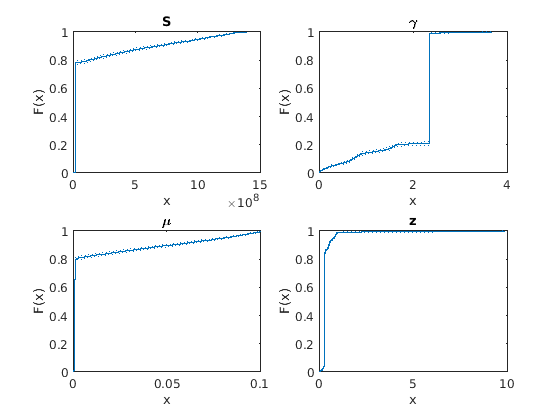

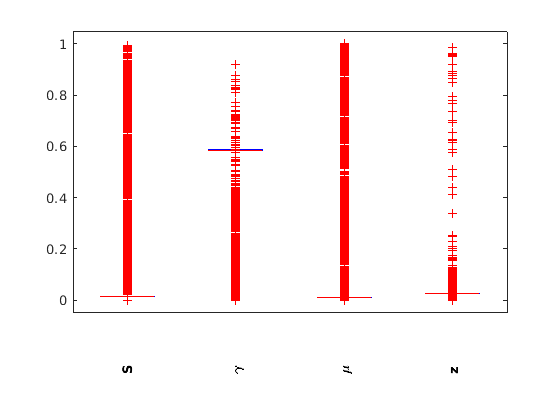

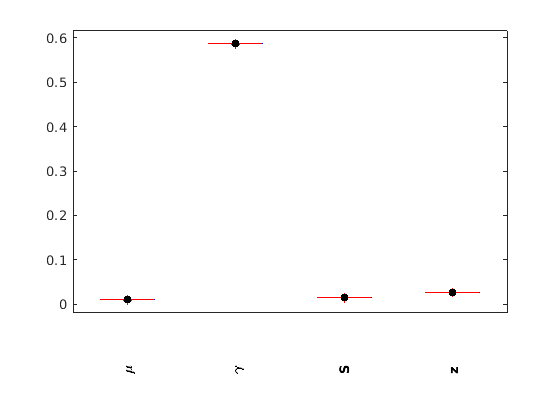

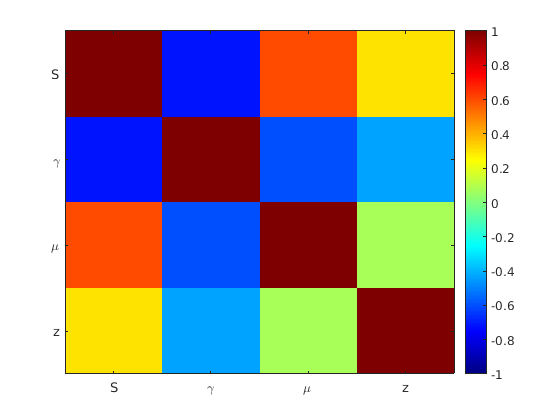

T = 4×4 table
                       Range               Nominal            Est           index 
              ________________________    __________    _______________    _______

    S         1.1494e+07    3.3321e+07    2.2407e+07    [1×5000 double]    0.35834
    \gamma        2.3194         2.367        2.3432    [1×5000 double]    0.36521
    \mu       0.00019251     0.0019035      0.001048    [1×5000 double]    0.33775
    z            0.25108       0.29418       0.27263    [1×5000 double]      0.178


T_ia{1} = gsua_ia(T_save{1},Parameters,false,false);

disp(ModelNames(2))

complex


T = 4×4 table
                       Range               Nominal            Est           index 
              ________________________    __________    _______________    _______

    S         1.1494e+07    3.3321e+07    2.2407e+07    [1×5000 double]    0.35834
    \gamma        2.3194         2.367        2.3432    [1×5000 double]    0.36521
    \mu       0.00019251     0.0019035      0.001048    [1×5000 double]    0.33775
    z            0.25108       0.29418       0.27263    [1×5000 double]      0.178


T_ia{2} = gsua_ia(T_save{2},Parameters,false,false);

**Sensitivity analisys for estimation intervals**

N = 10000;
M = gsua_dmatrix(T, N, 'Method', 'Sobol');

T_save{1} = gsua_sa(M,T_save{1});

Current outputs:2  4
Progress: 17%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:6
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 18:17:21
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:0:6
Remaining time (h:m:s): 0:0:4
Elapsed time (h:m:s): 0:0:2
Estimated stop time (h:m:s): 18:17:19
Number of simulations: 30000
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 0:0:40
Remaining time (h:m:s): 0:0:20
Elapsed time (h:m:s): 0:0:20
Estimated stop time (h:m:s): 18:17:54
Number of simulations: 30000
Progress: 67%
Estimated processing time (h:m:s): 0:0:31
Remaining time (h:m:s): 0:0:10
Elapsed time (h:m:s): 0:0:21
Estimated stop time (h:m:s): 18:17:45
Number of simulations: 30000
Progress: 84%
Estimated processing time (h:m:s): 0:0:26
Remaining time (h:m:s): 0:0:4
Elapsed time (h:m:s): 0:0:21
Estimated stop time (h:m:s): 18:17:39
Number of simulations: 30000
Progress: 100%
Estimated processing time (

sum(T_save{1}.Si)/sum(abs(T_save{1}.Si))

ans = 1

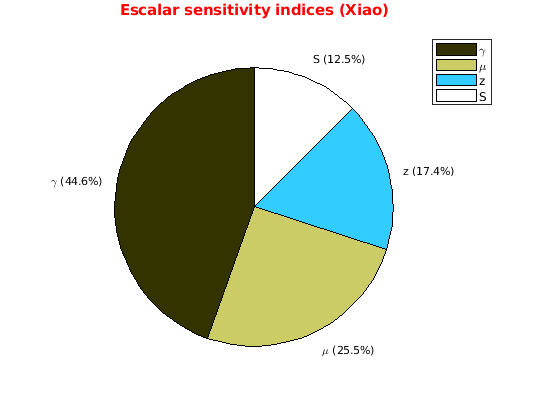

figure
gsua_plot('Pie',T_save{1},T_save{1}.STi)

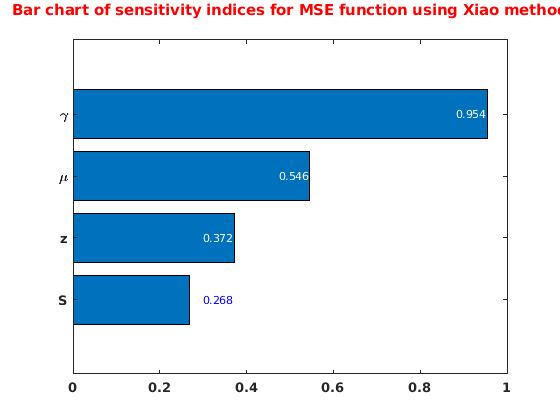

figure
gsua_plot('Bar',T_save{1},T_save{1}.STi)

T_save{2} = gsua_sa(M,T_save{2});

Current outputs:2  4
Progress: 17%
Estimated processing time (h:m:s): 0:0:3
Remaining time (h:m:s): 0:0:2
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 18:17:39
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:0:3
Remaining time (h:m:s): 0:0:2
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 18:17:39
Number of simulations: 30000
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 0:0:38
Remaining time (h:m:s): 0:0:19
Elapsed time (h:m:s): 0:0:19
Estimated stop time (h:m:s): 18:18:15
Number of simulations: 30000
Progress: 67%
Estimated processing time (h:m:s): 0:0:30
Remaining time (h:m:s): 0:0:10
Elapsed time (h:m:s): 0:0:20
Estimated stop time (h:m:s): 18:18:6
Number of simulations: 30000
Progress: 84%
Estimated processing time (h:m:s): 0:0:25
Remaining time (h:m:s): 0:0:4
Elapsed time (h:m:s): 0:0:21
Estimated stop time (h:m:s): 18:18:1
Number of simulations: 30000
Progress: 100%
Estimated processing time (h:

sum(T_save{2}.Si)/sum(abs(T_save{2}.Si))

ans = 1

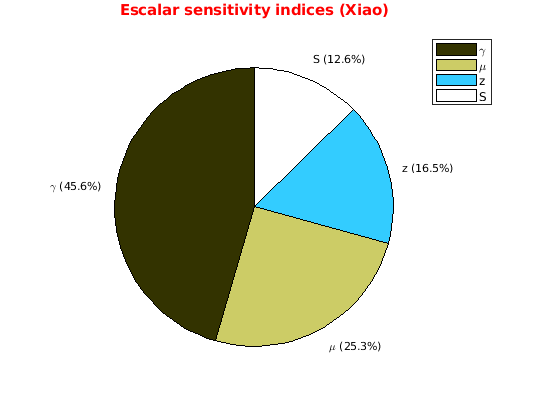

figure
gsua_plot('Pie',T_save{2},T_save{2}.STi)

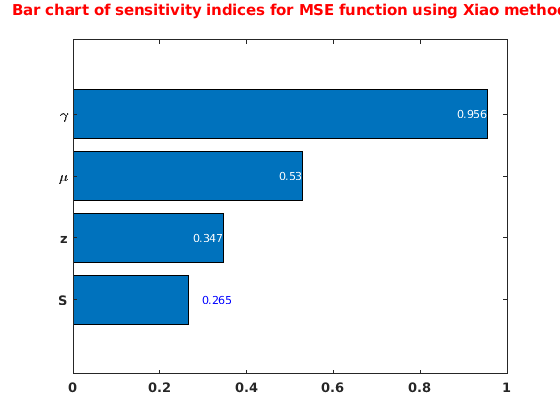

figure
gsua_plot('Bar',T_save{2},T_save{2}.STi)

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 19:1:48
Number of simulations: 1000


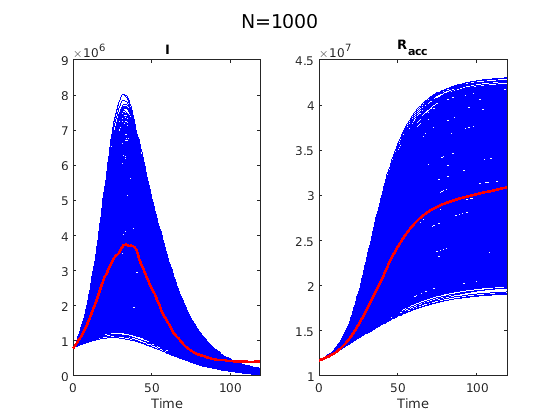

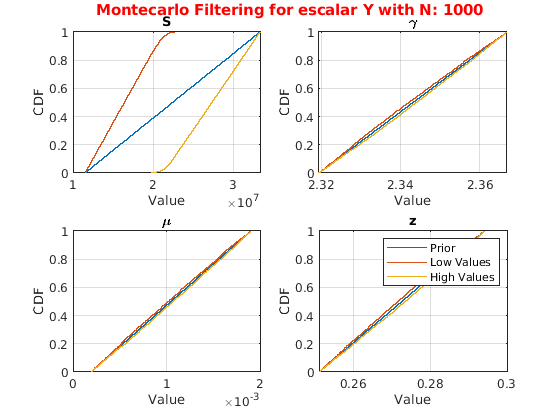

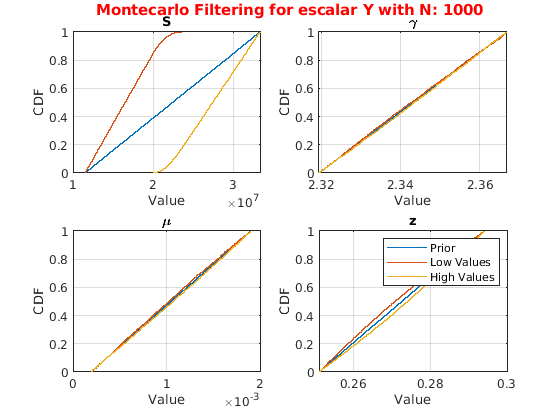

N = 1000;
M = gsua_dmatrix(T_ia{1}, N, 'Method','Sobol');  
gsua_ua(M, T_ia{1},'xdata', xdata, 'ynom', ydata, 'parallel', false);

N = 10000;

M = gsua_dmatrix(T_ia{1}, N, 'Method', 'Sobol');
T_ia{1} = gsua_sa(M,T_ia{1});

Current outputs:1  2  3
Progress: 17%
Estimated processing time (h:m:s): 0:0:52
Remaining time (h:m:s): 0:0:43
Elapsed time (h:m:s): 0:0:8
Estimated stop time (h:m:s): 9:45:15
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:0:49
Remaining time (h:m:s): 0:0:32
Elapsed time (h:m:s): 0:0:16
Estimated stop time (h:m:s): 9:45:12
Number of simulations: 30000
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 0:26:28
Remaining time (h:m:s): 0:13:14
Elapsed time (h:m:s): 0:13:14
Estimated stop time (h:m:s): 10:10:51
Number of simulations: 30000
Progress: 67%
Estimated processing time (h:m:s): 0:20:3
Remaining time (h:m:s): 0:6:41
Elapsed time (h:m:s): 0:13:22
Estimated stop time (h:m:s): 10:4:26
Number of simulations: 30000
Progress: 84%
Estimated processing time (h:m:s): 0:16:12
Remaining time (h:m:s): 0:2:42
Elapsed time (h:m:s): 0:13:30
Estimated stop time (h:m:s): 10:0:35
Number of simulations: 30000
Progress: 100%
Estimated proces

sum(T_ia{1}.Si)/sum(abs(T_ia{1}.Si))

ans = 1

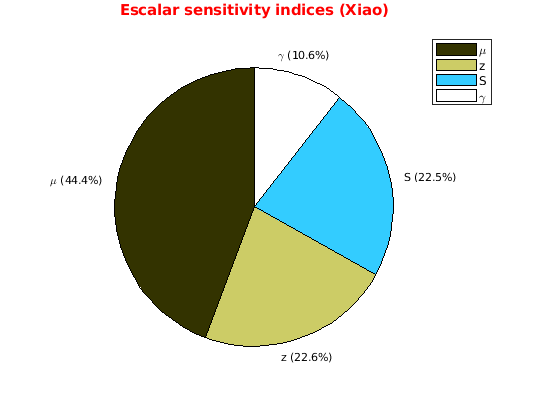

figure
gsua_plot('Pie',T_ia{1},T_ia{1}.STi)

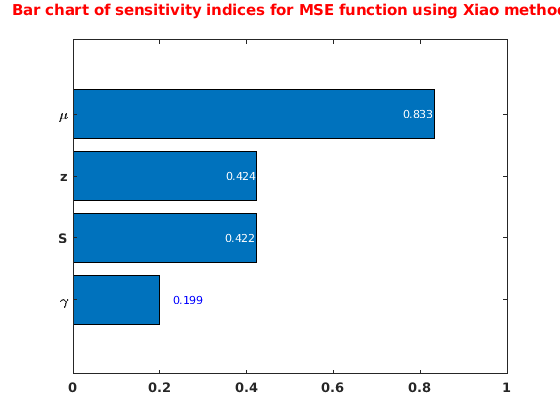

figure
gsua_plot('Bar',T_ia{1},T_ia{1}.STi)

M = gsua_dmatrix(T_ia{2}, N, 'Method', 'Sobol');
T_ia{2} = gsua_sa(M,T_ia{2});

Current outputs:1  2  3
Progress: 17%
Estimated processing time (h:m:s): 0:1:51
Remaining time (h:m:s): 0:1:32
Elapsed time (h:m:s): 0:0:18
Estimated stop time (h:m:s): 9:59:54
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:1:52
Remaining time (h:m:s): 0:1:15
Elapsed time (h:m:s): 0:0:37
Estimated stop time (h:m:s): 9:59:55
Number of simulations: 30000
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 1:31:48
Remaining time (h:m:s): 0:45:54
Elapsed time (h:m:s): 0:45:54
Estimated stop time (h:m:s): 11:29:51
Number of simulations: 30000
Progress: 67%
Estimated processing time (h:m:s): 1:9:25
Remaining time (h:m:s): 0:23:8
Elapsed time (h:m:s): 0:46:17
Estimated stop time (h:m:s): 11:7:28
Number of simulations: 30000
Progress: 84%
Estimated processing time (h:m:s): 0:56:0
Remaining time (h:m:s): 0:9:20
Elapsed time (h:m:s): 0:46:40
Estimated stop time (h:m:s): 10:54:3
Number of simulations: 30000
Progress: 100%
Estimated proces

sum(T_ia{2}.Si)/sum(abs(T_ia{2}.Si))

ans = 1

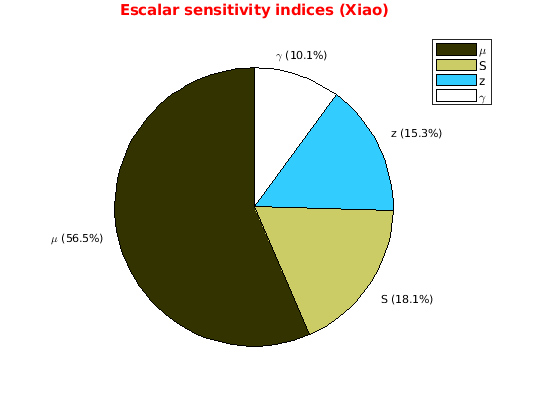

figure
gsua_plot('Pie',T_ia{2},T_ia{2}.STi)

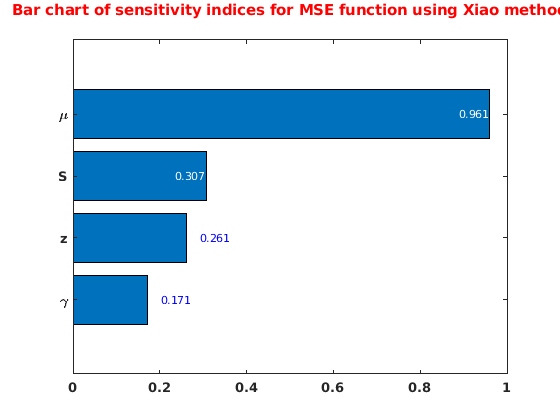

figure
gsua_plot('Bar',T_ia{2},T_ia{2}.STi)

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 19:2:2
Number of simulations: 1000


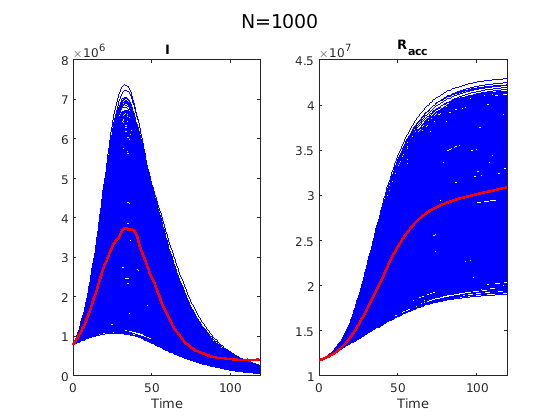

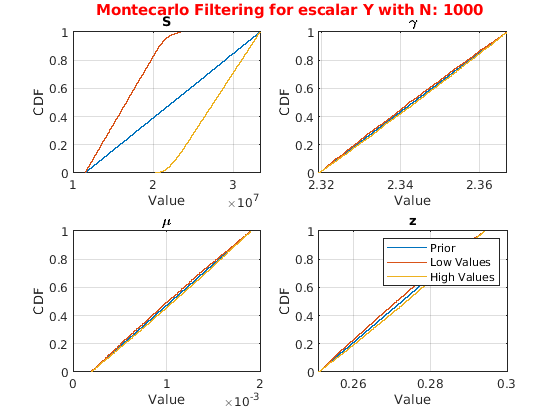

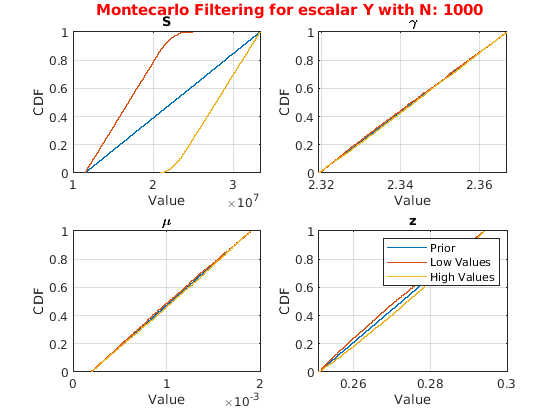

M = gsua_dmatrix(T_ia{2}, N, 'Method','Sobol');  
gsua_ua(M, T_ia{2},'xdata', xdata, 'ynom', ydata, 'parallel', false);